# Sensing System - Performance Evaluation

## Initialize the Evaluation Script

clear;
c = clock;
seed = floor(sum(c));
rng(seed);
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
% file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
 file_path = "4GHz.json";

config_path = david_path + file_path;

### Generate a test set parameters for evaluating performance

%specify maximum constraints
valid_slopes = [1,100];
valid_chirp_periods = [15,100];
valid_BWs_MHz = [30,3500];
num_adc_samples = 256;
num_chirps = 128;
num_cases = 200;

[slopes,chirp_periods,adc_sampling_rates] = ...
    characterization_functions.initialize_sensing_subsystem_test_cases_general(num_cases, ...
                valid_slopes, ...
                valid_chirp_periods, ...
                valid_BWs_MHz, ...
                num_adc_samples);

configurations_passed = characterization_functions.check_test_configurations(slopes, ...
    chirp_periods, ...
    adc_sampling_rates, ...
    num_adc_samples, ...
    config_path);

All Configurations passed 


### Run all of the test configurations and save results to a file

% slopes = slopes(33:end,:);
% chirp_periods = chirp_periods(33:end,:);
% adc_sampling_rates = adc_sampling_rates(33:end,:);
% num_cases = num_cases - 33;

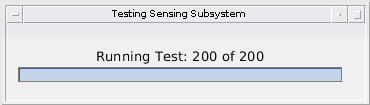

frames_to_compute = 7;

[testing_data_parameter_estimations, ...
    testing_data_frame_start_prediction_errors]...
    = characterization_functions.run_sensing_performance_test_cases( ...
        num_cases, ...
        frames_to_compute, ...
        slopes, ...
        chirp_periods, ...
        adc_sampling_rates, ...
        num_adc_samples, ...
        num_chirps, ...
        config_path, ...
        "sensing_subsystem_test_data"); 

### Plot Configuration Informatoin

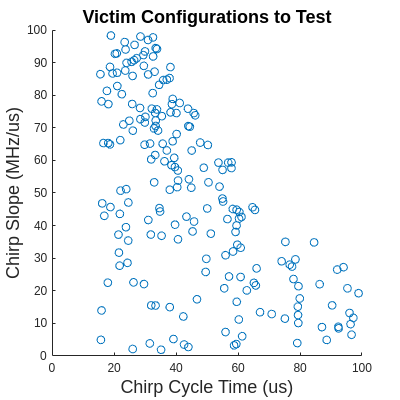

read_file_path = "sensing_subsystem_test_data_parameter_estimations.csv";
characterization_functions.plot_test_configurations(read_file_path);

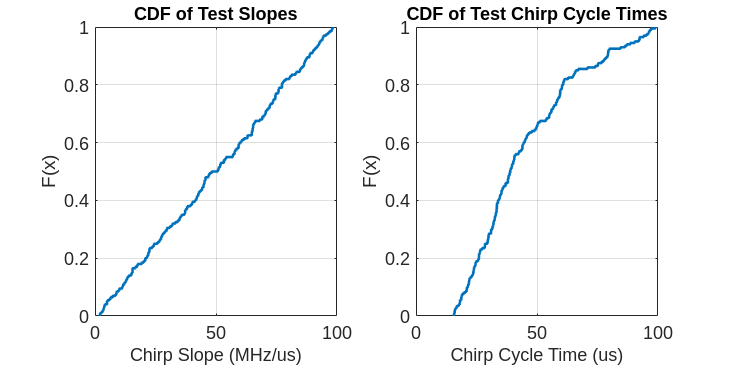

characterization_functions.plot_test_configuration_cdfs(read_file_path);

### Plot testing results

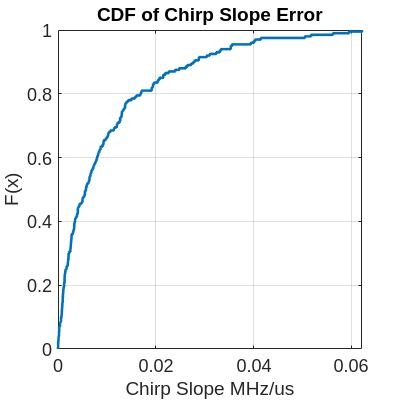

summary_table = 1×5 table
    Mean (MHz/us)    Variance (MHz/us)^2    MSE (MHz/us)^2    95th Percentile (MHz/us)    Percent Failed Trials
    _____________    ___________________    ______________    ________________________    _____________________

       0.01019           0.00014992            0.000253               0.035453                      0          


%plot the cdf of the chirp slope errors
read_file_path = "sensing_subsystem_test_data_parameter_estimations.csv";
actual_values_idx = 1;
estimated_vals_idx = 5;
abs_errors_idx = 8;
metric_title = "Chirp Slope";
metric_units = "MHz/us";
percentile = 95;
scale_factor = 1;
summary_table = characterization_functions.generate_testing_summary(...
    read_file_path,...
    actual_values_idx,...
    estimated_vals_idx,...
    abs_errors_idx,...
    metric_title,...
    metric_units,...
    percentile,...
    scale_factor)

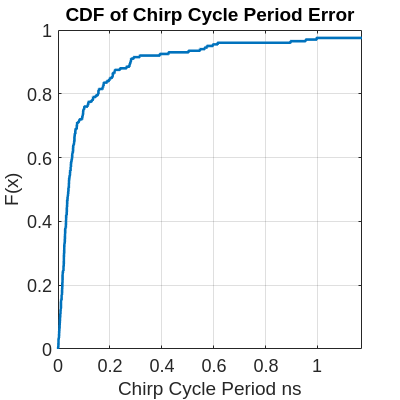

summary_table = 1×5 table
    Mean (ns)    Variance (ns)^2    MSE (ns)^2    95th Percentile (ns)    Percent Failed Trials
    _________    _______________    __________    ____________________    _____________________

     0.14344         0.14493         0.16478            0.58597                     0          


%chirp cycle period
read_file_path = "sensing_subsystem_test_data_parameter_estimations.csv";
actual_values_idx = 2;
estimated_vals_idx = 6;
abs_errors_idx =9;
metric_title = "Chirp Cycle Period";
metric_units = "ns";
percentile = 95;
scale_factor = 1e3;
summary_table = characterization_functions.generate_testing_summary(...
    read_file_path,...
    actual_values_idx,...
    estimated_vals_idx,...
    abs_errors_idx,...
    metric_title,...
    metric_units,...
    percentile,...
    scale_factor)

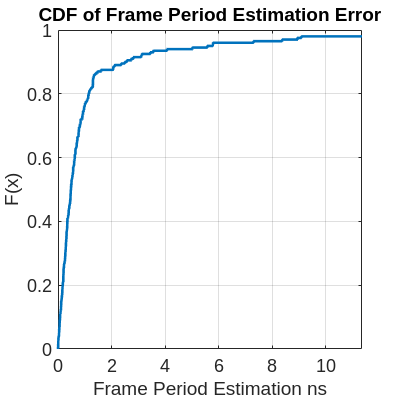

summary_table = 1×5 table
    Mean (ns)    Variance (ns)^2    MSE (ns)^2    95th Percentile (ns)    Percent Failed Trials
    _________    _______________    __________    ____________________    _____________________

     1.3706          14.955           16.759             5.6729                     0          


read_file_path = "sensing_subsystem_test_data_parameter_estimations.csv";
actual_values_idx = 3;
estimated_vals_idx = 7;
abs_errors_idx =10;
metric_title = "Frame Period Estimation";
metric_units = "ns";
percentile = 95;
scale_factor = 1e6;
summary_table = characterization_functions.generate_testing_summary(...
    read_file_path,...
    actual_values_idx,...
    estimated_vals_idx,...
    abs_errors_idx,...
    metric_title,...
    metric_units,...
    percentile,...
    scale_factor)

## Evaluating Frame Estimation Error Accuracy

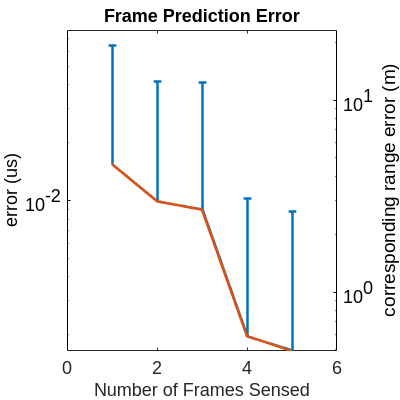

read_file_path = "sensing_subsystem_test_data_frame_start_time_prediction_errors.csv";
use_log_scale = true;
characterization_functions.plot_predicted_start_time_errors(read_file_path,use_log_scale);